**Numerical Methods Midterm Exam 2023 - Solutions**

**60 Marks**

1. (a) Where do the following 2 polynomials intersect on the real line?

$\(p_1\left(x\right)= x^8+x^7 - 7x^4 + 4x$,    $\(p_2\left(x\right)= 1+2x-5x^4$

clf reset
poly1 = [1, 1, 0, 0, -7, 0, 0 ,4, 0];
poly2 = [-5, 0, 0, 2, 1];
% poly2 = [1, 2, 0, 0, -5];
rootP1 = roots(poly1);
rootP2 = roots(poly2);
realRootsP1 = rootP1(imag(rootP1)==0);
realRootsP2 = rootP2(imag(rootP2)==0);
disp(rootP1);

   0.0000 + 0.0000i
  -1.9754 + 0.0000i
  -0.1768 + 1.5537i
  -0.1768 - 1.5537i
   1.3127 + 0.0000i
   0.8905 + 0.0000i
  -0.4370 + 0.7193i
  -0.4370 - 0.7193i



disp(realRootsP1);

         0
   -1.9754
    1.3127
    0.8905



disp(rootP2);

   0.8586 + 0.0000i
  -0.2187 + 0.7107i
  -0.2187 - 0.7107i
  -0.4213 + 0.0000i



disp(realRootsP2);

    0.8586
   -0.4213



x = -5:0.1:5;
p1 = @(x) x.^8 + x.^7 + 7*x.^4 + 4*x;
p2 = @(x) 1 + 2*x - 5*x.^4;
p3 = @(x) x.^8 + x.^7 + 7*x.^4 + 2*x -1 + 5*x.^4;
fplot(p1, [-1, 1]);
hold on
fplot(p2, [-1, 1]);
% fplot(p3, [-1, 1]);

% plot(realRootsP1, 0, 'g')

syms x
dp1 = diff(p1, x)

$$dp1 = 8\,x^{7}+7\,x^{6}+28\,x^{3}+4$$

dp2 = diff(p2, x)

$$dp2 = 2-20\,x^{3}$$

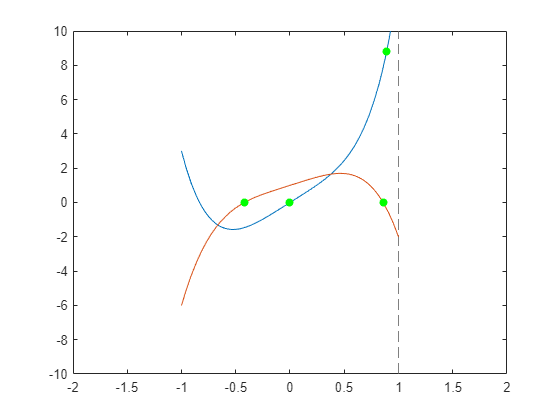

% fplot(dp1, [-1, 1]);
% fplot(dp2, [-1, 1]);
% legend('p1', 'p2', 'dp1', 'dp2');
scatter(realRootsP1, p1(realRootsP1), 'go', 'filled');
scatter(realRootsP2, p2(realRootsP2), 'go', 'filled');
hold off
xlim([-2, 2]);
ylim([-10, 10])

(b) Plot both polyomials on the same graph and mark their intersections with large red circles. Make sure you choose your range of values so that the intersections are clearly visible.

% Enter solution here

2.  The deflection of the cantilever beam at a distance $x$ from the fixed end is given by the nonlinear equation:


$$y(x)=\frac{Px^3}{3EI}-\frac{PLx^2}{2EI}$$


where $y$ is the deflection. You are given:

- Young's Modulus (E): $2.1 \times 10^9 $ N/m²

- Moment of Inertia (I): $3.5 \times 10^{-4} \text{ m}^4$

- Applied Load (P): 8 kN

- Beam Length (L): 3 m

Determine the location, $x$, where the deflection is 2cm.

clf reset
E = 3.1*10.^9;
I = 3.5*10.^-4;
P = 8;
L = 3;
f = @(x) ((P*x.^3)/(3*E*I)) - (P*L*x.^2)/(2*E*I)-2;
fplot(f, [50, 150]);
hold on
bracket = incsearch_stepsize(f, 50, 150, 0.1);

number of brackets:
     1



disp(bracket);

   94.8000   94.9000



size_b=size(bracket);
roots = bisect(f,94.8,94.9,0.0001);

  -2.3882e-04



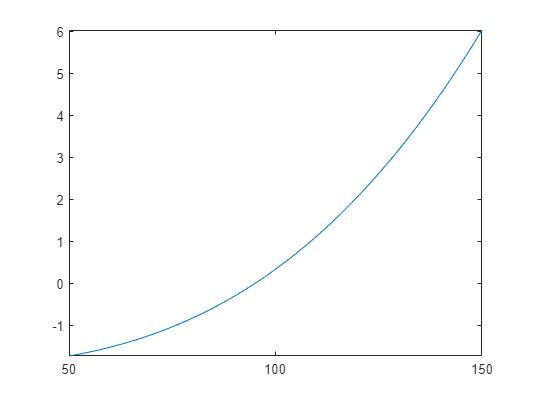

disp(f(roots));
plot(roots, f(roots), 'g')

3. Find where the following 2 functions intersect.


$$f(x, y) = e^{-\frac{x}{2}}\cos(2y) + \frac{1}{4}\\
g(x, y) = x^2+y^2-1$$


clf reset
f = @(x, y) exp(-x./2)*cos(2*y)+1/4;
g = @(x, y)  x.^2 + y.^2 -1;
fimplicit(f, [-10, 10])

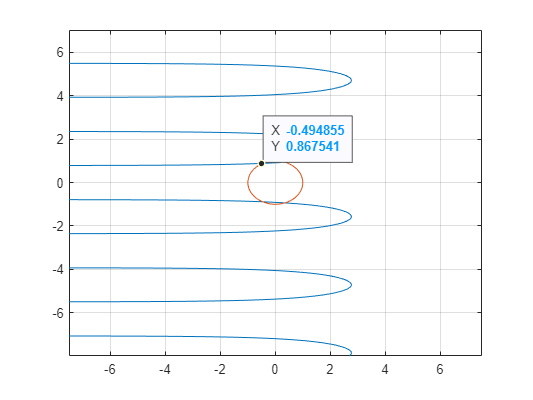

hold on
fimplicit(g, [-10, 10])
grid on

[x, fx] = fsolve(@nonlin, [-0.5,2]);

   -0.5000

     2



Error using vertcat
Dimensions of arrays being concatenated are not consistent.

Error in numerical_methods_midterm_2023>nonlin (line 59)
f = [exp(-x/2)*cos(2*y)+1/4; x.^2 + y.^2 -1];

Error in fsolve (line 260)
            fuser = feval(funfcn{3},x,varargin{:});

Caused by:
    Failure in ini

% [x, fx] = fsolve(@(x)[f(x);g(x)], [-0.5,-1])

4. From the information in the table below, find some combination of nonfat milk, soy flour, and whey that provide the exact amounts of protein, carbohydrate, and fat supplied by the Cambridge diet in one day.

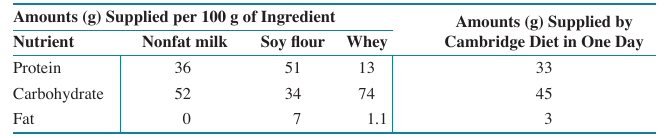

data = table({'Protein'; 'Carbohydrate'; 'Fat'}, [36; 52; 0], [36; 52; 0], [13; 74; 1.1], [33; 45; 3]);


5.  Create a root finding method based on the following iterative formula:

Use it to find all roots of the following function to 4 decimal places accuracy on the interval $(-\pi, \pi)$. Plot the graph and the roots on the same axes with the roots marked with large red circles.

% Enter solution here


 --- FUNCTIONS ---

A space to place your functions so that after running the code blocks below you can then use them in the scripts above.

function f = nonlin(X)
x = X(1);
disp(X(1));
y = X(2);
disp(X(2));
f = [exp(-x/2)*cos(2*y)+1/4; x.^2 + y.^2 -1];
end

function xb = incsearch_stepsize(func,xmin,xmax,h)

x = xmin:h:xmax;
f = func(x);
nb = 0; xb = [];
for k=1:length(x)-1
    if f(k)*f(k+1)<=0
        nb = nb+1;
        xb(nb,1) = x(k);
        xb(nb,2) = x(k+1);
    end
end
if isempty(xb)
    disp('no bracket found')
else
    disp('number of brackets:')
    disp(nb)
end
end

function [root,ea,iter] = bisect(func,xl,xu,es)
flag = true;
test = func(xl)*func(xu);
if test>0
    error('no sign change')
end

if test == 0
    flag = false;
    ea = 0;
    if func(xl) == 0
        root = xl;
    elseif func(xu) == 0
        root = xu;
    end
end

iter = 0;
xr=xl;
while flag
    xrold = xr;
    xr = (xl+xu)/2;
    iter = iter + 1;
    if xr ~= 0
        ea = abs((xr-xrold)/xr);
    end

    
    
    test = func(xl)*func(xr);
    if test<0
        xu = xr;
    elseif test > 0
        xl=xr;
    else
        ea=0;
 
    end

    root = xr;

    if ea<=es
        break
    end
end
end